## HilbertIIR:  IIR form of a Hilbert Transformer

### Motivation

Our need is for a Hilbert transform of non-stationary (and possibly non-linear) fundamental electrical power system signals.  The goal is to analyse segments one nominal period (1/50 s or 1/60 s) of data at a time and find the instantanious frequency and ROCOF.  MATLAB's HILBERT function uses FFT followerd by iFFT techniques which have end effect issues, leakage issues, and in-particular, do not handle non-stationry signals well.  The hope is that an IIR Hilbert transformer will suit our needs.

### Real-world needs and conditions

Since we cannot implement an ideal Hilbert transformer, We need to look at the real-world needs.  We hope for instantanious frequency accuracy within 0.005 Hz and ROCOF accuracy of 0.4 Hz/s.  The bandwidth for this level of accurcy is desired to be from 25 Hz to 75 Hz.  If that cannot be achieved, then bandwidth from 45 Hz to 65 Hz is the minimum.  In normalized terms, if we assume a sample rate of 4800 samples per second (SPS) then we want 0.0187 to 0.0271 bandwidth at worst or 0.0104 to 0.0313 at best.  On the unit circle that is:

BW50 = [0.0187, 0.0271]*pi;
disp(sprintf ('At 4800 SPS, 25 Hz to 75 Hz  in radians = %f radians to %f redians.', BW50(1),BW50(2)))

At 4800 SPS, 25 Hz to 75 Hz  in radians = 0.058748 radians to 0.085137 redians.


disp(sprintf('or %f degrees to %f degrees on the unit circle',BW50(1)*180/pi,BW50(2)*180/pi))

or 3.366000 degrees to 4.878000 degrees on the unit circle


 For most Hilbert transofomers, this is too close to DC to be accurate.  Sample rate reduction (by at least an order of 4) may help.

## IIR

### Topology 

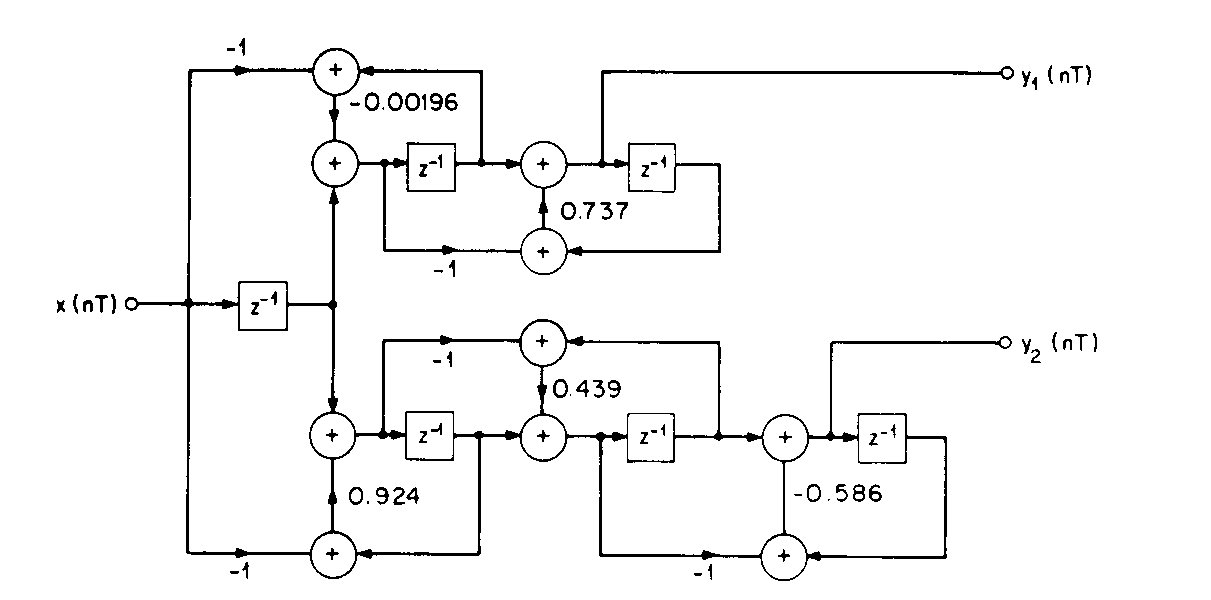

From Theory and Implementation of Discrete Hilbert Transform, B. Gold, A.V. Oppenheim, C.M. Rader.

The above Figure 9 shows an IIR allp-pass pair to implement the Hilbert transform.  For our needs, the coefficients will likely be different.  The upper all-pass filter delays the  real part to aligh with the imaginary part from the lower section.

The difference equation is:

#### Upper Section:

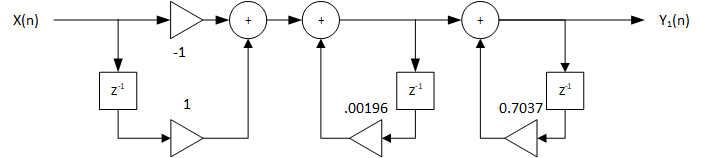

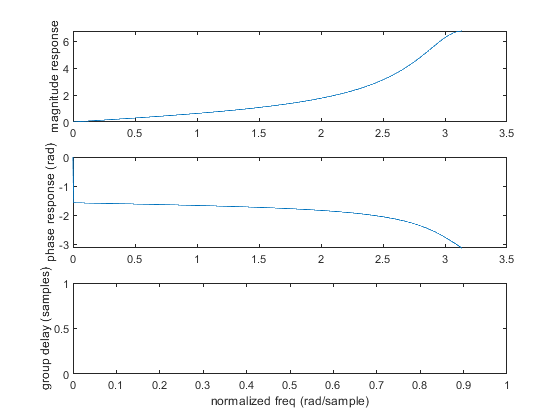

b1 = [-1,1];
a1 = [1,.00196];
b2 = 1;
a2 = [1,0.7037];
b = conv(b1,b2);
a = conv(a1,a2);
[h,w] = freqz(b,a);
g = grpdelay(b,a);

subplot(3,1,1)
plot(w,abs(h)), ylabel('magnitude response')
subplot(3,1,2)
plot(w,unwrap(angle(h))), ylabel('phase response (rad)')
subplot(3,1,3)
plot(w,g), xlabel('normalized freq (rad/sample)'), ylabel('group delay (samples)')
cla,figure()

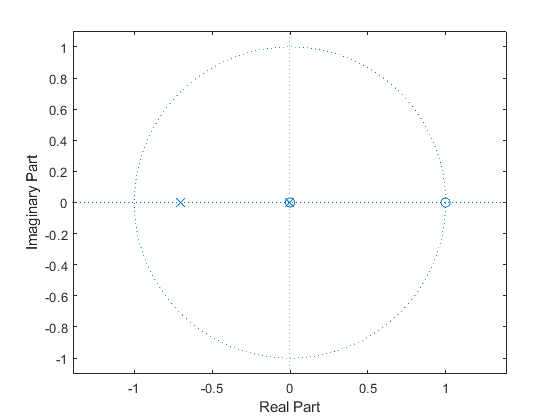

zplane(b,a);

### FIR

see Optimum_masking_levels_and_coefficient_sparseness_for_Hilbert_transformers_and_half-band_filters_designed_using_the_frequency-response_masking_technique.  Lim et al 2005

This example comes directly from https://www.intechopen.com/chapters/39362

% d = 0.01;  % passbad ripple (smaller values see Lim Table 1 )
% 
% % Lower and upper bands and length from https://www.intechopen.com/chapters/39362
% w_L = 0.1*pi; w_H = 0.9*pi;
% L = 27
% 
% % lets see if we can make it much lower
% %w_L = 0.0187*pi; w_H = 0.1*pi;
% %L = 
% 
% h = fir pm(L-1,[w_L/pi w_H/pi],[1 1],'hilbert');
% [H, w] = freqz(h,1);
% figure; stem(0:length(h)-1, h,'fill')
% figure; plot(w/pi, abs(H))
% zplane(h,1)

This example is too high frequency and we do not need this wide bandwidth, we need to get the frequency down (we may need to cascase a couple of half band filters to do that, we shall see...

Let the transition witth be 